%% 1. Wykres: zmienny SCS i min P_switch
% Parametry stałe
T_total = 2500;
scs = [15, 30, 60, 120];
SSSG0_frequency = 1;
SSSG1_frequency = 8;
P_switch = [25, 25, 25, 40];
packet_frequency = [100, 250, 500, 5000];
packet_data_duration = 20;
dci_latency = 6;

% Inicjalizacja wyników
energy_gains_1 = zeros(length(scs), length(packet_frequency));
mean_delays_1 = zeros(length(scs), length(packet_frequency));

% Symulacja
for scs_idx = 1:length(scs)
    for freq_idx = 1:length(packet_frequency)
        [energy_gains_1(scs_idx, freq_idx), mean_delays_1(scs_idx, freq_idx)] = ...
            sssg_switching_with_trigger_script(...
                T_total, scs(scs_idx), SSSG0_frequency, SSSG1_frequency, ...
                P_switch(scs_idx), packet_frequency(freq_idx), ...
                packet_data_duration, dci_latency);
    end
end


=== Starting DRX Simulation ===
Total simulation time: 2500 ms
SSSG0 frequency in slots: 1 
SSSG1 frequency in slots: 8 
P switch value in slots: 25 ms
Packet frequency: 100 ms
Buffor in ms indicating when DCI 2_0 is send: 6 
Packet reception time: 20 ms

LIGHT SLEEP
SSSG1 no data: 250.64
Time 0.00 ms | SSSG0 monitoring | Counter: 5 | Energy used: 100.00 mJ (switching) / 100.00 mJ (no switch)
Time 1.00 ms | SSSG0 monitoring | Counter: 4 | Energy used: 200.00 mJ (switching) / 200.00 mJ (no switch)
Time 2.00 ms | SSSG0 monitoring | Counter: 3 | Energy used: 300.00 mJ (switching) / 300.00 mJ (no switch)
Time 3.00 ms | SSSG0 monitoring | Counter: 2 | Energy used: 400.00 mJ (switching) / 400.00 mJ (no switch)
Time 4.00 ms | SSSG0 monitoring | Counter: 1 | Energy used: 500.00 mJ (switching) / 500.00 mJ (no switch)
Time 5.00 ms | SSSG0 monitoring | Counter: 0 | Energy used: 600.00 mJ (switching) / 600.00 mJ (no switch)
Time 6.00 ms | SSSG0 monitoring | Switching to p_switch monitoring (count

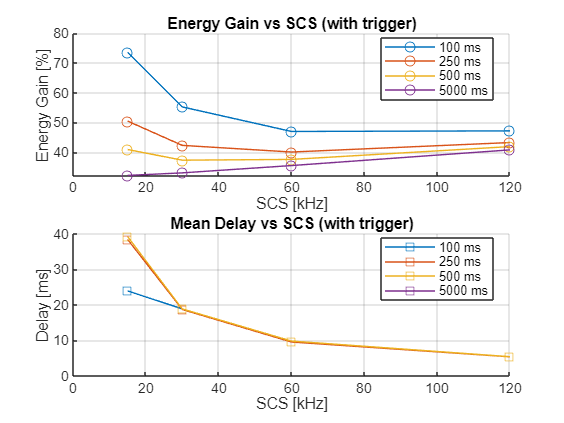


% Rysowanie wykresów
figure;
subplot(2,1,1);
hold on;
for freq_idx = 1:length(packet_frequency)
    plot(scs, energy_gains_1(:, freq_idx), '-o', ...
        'DisplayName', sprintf('%d ms', packet_frequency(freq_idx)));
end
title('Energy Gain vs SCS (with trigger)');
xlabel('SCS [kHz]'); ylabel('Energy Gain [%]');
legend('Location','best'); grid on; hold off;

subplot(2,1,2);
hold on;
for freq_idx = 1:length(packet_frequency)
    plot(scs, mean_delays_1(:, freq_idx), '-s', ...
        'DisplayName', sprintf('%d ms', packet_frequency(freq_idx)));
end
title('Mean Delay vs SCS (with trigger)');
xlabel('SCS [kHz]'); ylabel('Delay [ms]');
legend('Location','best'); grid on; hold off;

%% 2. Wykres: zmienny SSSG1_frequency
T_total = 3000;
scs = 30;
SSSG1_frequency = [2, 4, 5, 8, 10, 16, 20, 40, 80, 160];
packet_frequency = [250, 500, 750, 1000, 5000];

energy_gains_2 = zeros(length(SSSG1_frequency), length(packet_frequency));
mean_delays_2 = zeros(length(SSSG1_frequency), length(packet_frequency));

for sssg_idx = 1:length(SSSG1_frequency)
    for freq_idx = 1:length(packet_frequency)
        [energy_gains_2(sssg_idx, freq_idx), mean_delays_2(sssg_idx, freq_idx)] = ...
            sssg_switching_with_trigger_script(...
                T_total, scs, SSSG0_frequency, SSSG1_frequency(sssg_idx), ...
                P_switch, packet_frequency(freq_idx), ...
                packet_data_duration, dci_latency);
    end
end


=== Starting DRX Simulation ===
Total simulation time: 3000 ms
SSSG0 frequency in slots: 1 
SSSG1 frequency in slots: 2 
P switch value in slots: 25 ms
P switch value in slots: 25 ms
P switch value in slots: 25 ms
P switch value in slots: 40 ms
Packet frequency: 250 ms
Buffor in ms indicating when DCI 2_0 is send: 6 
Packet reception time: 20 ms

LIGHT SLEEP
SSSG1 no data: 70.64
Time 0.00 ms | SSSG0 monitoring | Counter: 2 | Energy used: 50.00 mJ (switching) / 50.00 mJ (no switch)
Time 0.50 ms | SSSG0 monitoring | Counter: 1 | Energy used: 100.00 mJ (switching) / 100.00 mJ (no switch)
Time 1.00 ms | SSSG0 monitoring | Counter: 0 | Energy used: 150.00 mJ (switching) / 150.00 mJ (no switch)
Time 1.50 ms | SSSG0 monitoring | Switching to p_switch monitoring (counter: 25)
Switching to p_switch monitoring (counter: 25)
Switching to p_switch monitoring (counter: 25)
Switching to p_switch monitoring (counter: 40)
Time 1.50 ms | SSSG0 monitoring | Counter: 24 | Energy used: 24.00 mJ (switchin

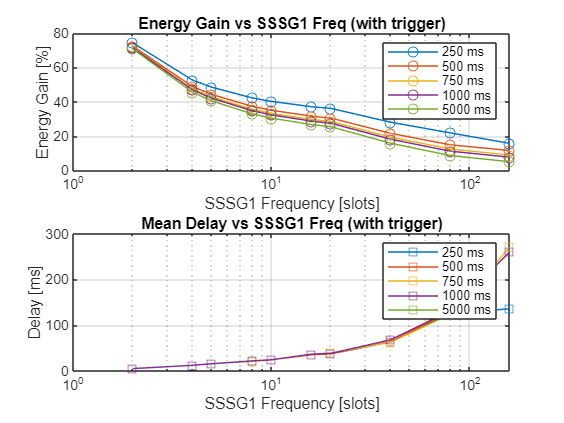


figure;
subplot(2,1,1);
semilogx(SSSG1_frequency, energy_gains_2, '-o');
title('Energy Gain vs SSSG1 Freq (with trigger)');
xlabel('SSSG1 Frequency [slots]'); ylabel('Energy Gain [%]');
legend(arrayfun(@(x) sprintf('%d ms', x), packet_frequency, 'UniformOutput', false));
grid on;

subplot(2,1,2);
semilogx(SSSG1_frequency, mean_delays_2, '-s');
title('Mean Delay vs SSSG1 Freq (with trigger)');
xlabel('SSSG1 Frequency [slots]'); ylabel('Delay [ms]');
legend(arrayfun(@(x) sprintf('%d ms', x), packet_frequency, 'UniformOutput', false));
grid on;

%% 3. Wykres: zmienny dci_latency
T_total = 2500;
scs = 30;
SSSG0_frequency = 1;
SSSG1_frequency = 8; % Stała wartość
P_switch = 25;
packet_frequency = [100, 250, 500, 5000];
packet_data_duration = 20;
dci_latency_values = [1, 2, 3, 4, 6, 8, 10, 12, 15, 20]; % Badane wartości

energy_gains_3 = zeros(length(dci_latency_values), length(packet_frequency));
mean_delays_3 = zeros(length(dci_latency_values), length(packet_frequency));

for dci_idx = 1:length(dci_latency_values)
    for freq_idx = 1:length(packet_frequency)
        [energy_gains_3(dci_idx, freq_idx), mean_delays_3(dci_idx, freq_idx)] = ...
            sssg_switching_with_trigger_script(...
                T_total, scs, SSSG0_frequency, SSSG1_frequency, ...
                P_switch, packet_frequency(freq_idx), ...
                packet_data_duration, dci_latency_values(dci_idx));
    end
end


=== Starting DRX Simulation ===
Total simulation time: 2500 ms
SSSG0 frequency in slots: 1 
SSSG1 frequency in slots: 8 
P switch value in slots: 25 ms
Packet frequency: 100 ms
Buffor in ms indicating when DCI 2_0 is send: 1 
Packet reception time: 20 ms

LIGHT SLEEP
SSSG1 no data: 130.64
Time 0.00 ms | SSSG0 monitoring | Counter: 0 | Energy used: 50.00 mJ (switching) / 50.00 mJ (no switch)
Time 0.50 ms | SSSG0 monitoring | Switching to p_switch monitoring (counter: 25)
Time 0.50 ms | SSSG0 monitoring | Counter: 24 | Energy used: 100.00 mJ (switching) / 100.00 mJ (no switch)
Time 1.00 ms | SSSG0 monitoring | Counter: 23 | Energy used: 150.00 mJ (switching) / 150.00 mJ (no switch)
Time 1.50 ms | SSSG0 monitoring | Counter: 22 | Energy used: 200.00 mJ (switching) / 200.00 mJ (no switch)
Time 2.00 ms | SSSG0 monitoring | Counter: 21 | Energy used: 250.00 mJ (switching) / 250.00 mJ (no switch)
Time 2.50 ms | SSSG0 monitoring | Counter: 20 | Energy used: 300.00 mJ (switching) / 300.00 mJ (

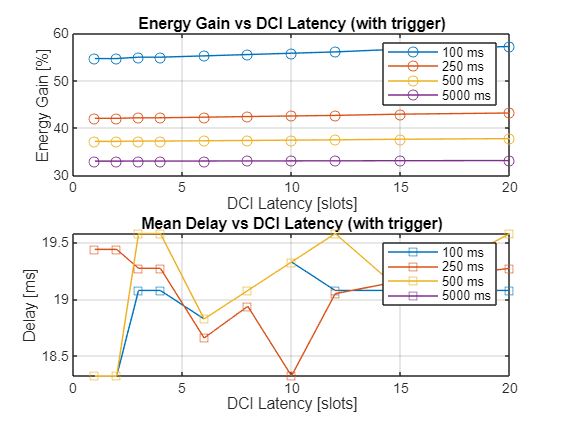


figure;
subplot(2,1,1);
plot(dci_latency_values, energy_gains_3, '-o');
title('Energy Gain vs DCI Latency (with trigger)');
xlabel('DCI Latency [slots]'); ylabel('Energy Gain [%]');
legend(arrayfun(@(x) sprintf('%d ms', x), packet_frequency, 'UniformOutput', false));
grid on;

subplot(2,1,2);
plot(dci_latency_values, mean_delays_3, '-s');
title('Mean Delay vs DCI Latency (with trigger)');
xlabel('DCI Latency [slots]'); ylabel('Delay [ms]');
legend(arrayfun(@(x) sprintf('%d ms', x), packet_frequency, 'UniformOutput', false));
grid on;


%dci_delay zrób jako sekundy - a nie slot - jako bufery powinny w czasie
%się tak samo wypełniać
%wykres with trigger i nie trigger
%zrob scripty 